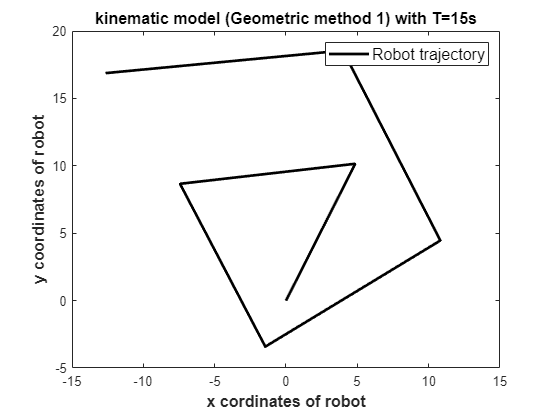

clear all; clc
% Sample code for Rectangular Integration based Kinematic model
T = 15; % Sampling time
ti = 0; % Initial time
tf = 100; % Final time
td = ti:T:tf; % Discrete time defined

tf = td(end);
% Due to discrete steps, t_d(end) is not necessarily equal to tf.
% That is why we need to recompute tf by assigning t_d(end) to it.
sl = length(td); % Number of samples in discrete time frame
wR = 0.3*cos(0.002*td); % Right wheel angular speed
wL = sin(0.002*td); % Left wheel angular speed
r = 5; % Radius of wheels [cm]
L = 10; % Width of robot platform [cm]
xd = zeros(1,sl); % Vector to store global x_n
yd = zeros(1,sl); % Vector to store global y_n
phd = zeros(1,sl); % Vector to store global \phi_n
for ii=1:sl-1
% note that we need to run this loop for one less iteration because
% the pose quantities have time index (ii+1)
vR=r*wR(ii);
vL=r*wL(ii);
v=(vR+vL)/2;
w=(vR-vL)/L;
dph=T*w;
xd(ii+1)=xd(ii)+v*T*cos(phd(ii)+dph/2);
yd(ii+1)=yd(ii)+v*T*sin(phd(ii)+dph/2);
phd(ii+1)=phd(ii)+dph;
end
plot(xd,yd,'k','linewidth',2);hold on;
xlabel("x cordinates of robot",'fontsize',12,'fontweight','bold');
ylabel("y coordinates of robot",'fontsize',12,'fontweight','bold');
title("kinematic model (Geometric method 1) with T=15s",'fontsize',12);
legend("Robot trajectory"),set(legend,'fontsize',12);